# Furuta Pendulum - Pole Placement

## 1. System Model

Load the data files directly. The first two Live Scripts calculate the equations and matrices. No external helper file is needed.

assert(isfolder('data') && isfolder('models'),'Set Current Folder to Furuta_Clean_Project.');
addpath('models','geometry');
load('data/Linear_Model_Data.mat');
load('data/Accepted_Controller_Data.mat');
A

A =          0         0    1.0000         0
         0         0         0    1.0000
   -0.0000    7.4894   -3.8338   -0.1496
    0.0000  141.7525   -2.7194   -2.8308


B

B = 1.0e+03 *

         0
         0
    6.6912
    4.7462


C

C =      1     0     0     0
     0     1     0     0


D

D =      0
     0


xe = x_equilibrium;
taue = tau_equilibrium;


## 2. Design Requirements

Use the same pulse and targets for all three controllers. After the pulse ends, the settling bands are +/-0.1 deg for the pendulum and +/-1 deg for the arm.

pendulum_settling_target = 2.5;  % s after pulse end
arm_settling_target = 8;          % s after pulse end
pendulum_peak_limit = 8;         % deg
torque_limit = 0.01;             % N m
t = (0:0.001:10)';
disturbance = 0.01*double(t>=1 & t<1.05);


## 3. Open-Loop Analysis

Check the open-loop poles, controllability and observability before designing the controller.

open_loop_poles = eig(A)

open_loop_poles =    -0.0000
   10.5276
  -13.5161
   -3.6761


controllability_rank = rank(ctrb(A,B))

controllability_rank = 4

observability_rank = rank(obsv(A,C))

observability_rank = 4

assert(controllability_rank==4 && observability_rank==4);


## 4. Controller Design

Follow the lecture steps: set response targets, check controllability, choose poles, then calculate K. The real poles below are the existing choice that passed the earlier project tests.

desired_poles = [-5,-6,-8,-10];
settling_estimate = 4/min(abs(real(desired_poles)))  % initial modal guide only

settling_estimate = 0.8000

K = place(A,B,desired_poles)

K =    -0.0026    0.1046   -0.0022    0.0078


assert(norm(K-K_pp)<1e-7,'Changed design: repeat full validation.');
% tau = taue - K*(x-xe).


## 5. Closed-Loop Stability

Check that all closed-loop poles have negative real parts. This proves local stability of the linear model. Then check the nonlinear simulation.

Acl = A-B*K;
Bd = B;
closed_loop_poles = eig(Acl)

closed_loop_poles =   -10.0000
   -8.0000
   -6.0000
   -5.0000


assert(all(real(closed_loop_poles)<0));


## 6. Implementation and Simulation

Apply the calculated gains to the matching controller block in Furuta_StudyF. Select the controller before each run. The simulation does not switch controllers or save model changes.

linear_states = lsim(ss(Acl,Bd,eye(4),zeros(4,1)),disturbance,t);
linear_torque = -linear_states*K';
model = 'Furuta_StudyF';
load_system(fullfile(pwd,'models',[model '.slx']));
assert(strcmp(get_param(model,'Dirty'),'off'),'Preserve unsaved model edits before this test.');
in = Simulink.SimulationInput(model);
in = in.setModelParameter('StopTime','10');
in = in.setBlockParameter([model '/Controller selector'],'controller_choice','Pole Placement');
in = in.setVariable('xe_controller',xe,'Workspace',model);
in = in.setVariable('taue_controller',taue,'Workspace',model);
in = in.setVariable('K_pp_controller',K,'Workspace',model);
simulation = sim(in);
xs = simulation.x_simscape; us = simulation.tau_controller;
[tx,ix] = unique(xs.Time); [tu,iu] = unique(us.Time);
x = interp1(tx,xs.Data(ix,:),t,'pchip') - xe';
u = interp1(tu,us.Data(iu,:),t,'pchip');


## 7. Results and Discussion

Plot the response and save this run for comparison. The external torque is added after the actuator limit. PID has integral action. Pole Placement and plain LQR may leave an arm offset under a constant load. These designs balance near upright; they do not swing up the pendulum.

figure('Name','Pole Placement response','Color','w'); tiledlayout(2,2);
nexttile; plot(t,rad2deg(linear_states(:,2)),'--',t,rad2deg(x(:,2)));
ylabel('Pendulum (deg)'); xlabel('Time (s)'); grid on; legend('Linear','Multibody');
nexttile; plot(t,rad2deg(linear_states(:,1)),'--',t,rad2deg(x(:,1)));
ylabel('Arm (deg)'); xlabel('Time (s)'); grid on;
nexttile; plot(t,linear_torque,'--',t,u);
ylabel('Actuator torque (N m)'); xlabel('Time (s)'); grid on;
nexttile; plot(t,x(:,3:4));
ylabel('Velocity (rad/s)'); xlabel('Time (s)'); grid on; legend('Arm','Pendulum');
sgtitle('Pole Placement | 0.01 N m arm pulse, 1.00-1.05 s');
performance = measure_response(t,x,u)

performance = 1×8 table
    PeakPendulum_deg    PeakArm_deg    PendulumSettling_s    ArmSettling_s    PeakTorque_Nm    RmsTorque_Nm    PendulumIAE_rad_s    SaturationFraction
    ________________    ___________    __________________    _____________    _____________    ____________    _________________    __________________

         3.0541           18.427             1.307               1.338          0.0088045       0.00069794         0.017122                 0         


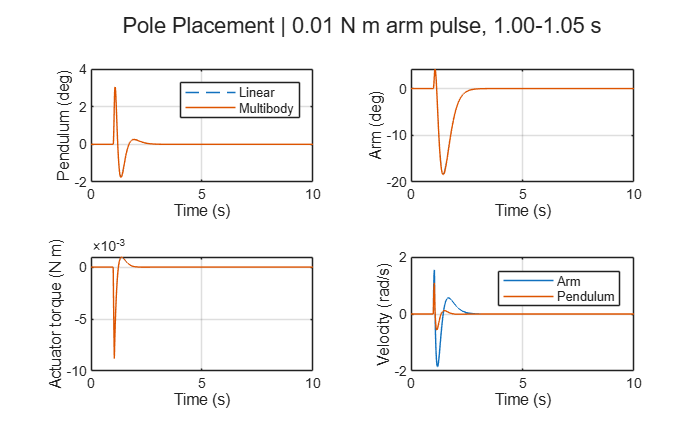

test = struct('pulse_Nm',0.01,'on_s',1,'off_s',1.05,'duration_s',10,'limit_Nm',0.01);
assert(performance.PeakPendulum_deg<=pendulum_peak_limit ...
    && performance.PendulumSettling_s<=pendulum_settling_target ...
    && performance.ArmSettling_s<=arm_settling_target);
save('results/PP_Result.mat','t','x','u','performance','test','closed_loop_poles','A','B');
drawnow; exportgraphics(gcf,'results/PP_Response.png','Resolution',140);

## Local functions

These short functions calculate performance inside this Live Script. No external helper file is needed.

function performance = measure_response(t,x,u)
% Settling bands: pendulum 0.1 deg, arm 1 deg, after pulse end.
performance = table(max(abs(rad2deg(x(:,2)))),max(abs(rad2deg(x(:,1)))), ...
    settling_time(t,x(:,2),deg2rad(0.1)),settling_time(t,x(:,1),deg2rad(1)), ...
    max(abs(u)),sqrt(trapz(t,u.^2)/(t(end)-t(1))), ...
    trapz(t,abs(x(:,2))),trapz(t,double(abs(u)>=0.01*(1-1e-6)))/(t(end)-t(1)), ...
    'VariableNames',{'PeakPendulum_deg','PeakArm_deg','PendulumSettling_s', ...
    'ArmSettling_s','PeakTorque_Nm','RmsTorque_Nm','PendulumIAE_rad_s','SaturationFraction'});
end

function value = settling_time(t,y,band)
outside = find(t>=1.05 & abs(y)>band);
if isempty(outside), value=0;
elseif outside(end)==numel(t), value=Inf;
else, value=t(outside(end)+1)-1.05;
end
end
